% Combined Simulation: PV Panel + Quadratic Boost Converter + RBF Neural Network
clc; clear; close all;

%% PV Panel Parameters
Isc = 8;               % Short circuit current (A)
Voc = 21;              % Open circuit voltage (V)
Vmpp = 17;             % Voltage at maximum power point (V)
Impp = 7.1;            % Current at maximum power point (A)
Ns = 72;               % Number of series-connected cells
Rs = 0.01;             % Series resistance (Ohms)
Rsh = 1000;            % Shunt resistance (Ohms)
T = 25 + 273.15;       % Cell temperature (K)
k = 1.38e-23;          % Boltzmann constant (J/K)
q = 1.6e-19;           % Electron charge (C)
Iph = Isc;             % Photocurrent approximation (A)
Vt = Ns * k * T / q;   % Thermal voltage (V)
I0 = Isc / (exp(Voc / Vt) - 1); % Reverse saturation current (A)

% PV Voltage Range
V_pv = linspace(0, Voc, 1000); % Voltage range (V)
I_pv = zeros(size(V_pv));      % Initialize current array (A)

% Solve PV Current Equation
for idx = 1:length(V_pv)
    f = @(I) Iph - I - I0 * (exp((V_pv(idx) + Rs * I) / Vt) - 1) - (V_pv(idx) + Rs * I) / Rsh;
    I_pv(idx) = fzero(f, Iph); % Initial guess is Iph
end

P_pv = V_pv .* I_pv; % PV Power

%% Quadratic Boost Converter Parameters
Vin = Vmpp; % Match PV panel Vmpp for input
L1 = 150e-6; % Inductor L1 (H)
L2 = 100e-6; % Inductor L2 (H)
C1 = 220e-6; % Capacitor C1 (F)
C2 = 100e-6; % Capacitor C2 (F)
Rload = 20; % Load resistance (Ohms)
Fs = 100e3; % Switching frequency (Hz)
D = 0.3;    % Duty cycle (initial guess)

% Time Parameters
t_end = 0.02; % Simulation time (s)
dt = 1/Fs / 1000; % Time step (s)
time = 0:dt:t_end;

% Initialize QBC Variables
iL1 = zeros(1, length(time)); % Inductor current L1
iL2 = zeros(1, length(time)); % Inductor current L2
vC1 = zeros(1, length(time)); % Capacitor voltage C1
vC2 = zeros(1, length(time)); % Capacitor voltage C2
vout = zeros(1, length(time)); % Output voltage
vC1(1) = Vin; % Initial C1 voltage
vC2(1) = Vin; % Initial C2 voltage

% QBC Simulation Loop
for k = 1:length(time)-1
    if mod(time(k), 1/Fs) < D/Fs % Switch ON
        diL1_dt = Vin / L1;
        diL2_dt = vC1(k) / L2;
        dvC1_dt = -iL1(k) / C1;
        dvC2_dt = 0; % C2 holds charge
    else % Switch OFF
        diL1_dt = (Vin - vC1(k)) / L1;
        diL2_dt = (vC2(k) - vC1(k)) / L2;
        dvC1_dt = iL1(k) / C1;
        dvC2_dt = abs(iL2(k) / C2);
    end
    
    % Euler Method for Updates
    iL1(k+1) = iL1(k) + diL1_dt * dt;
    iL2(k+1) = iL2(k) + diL2_dt * dt;
    vC1(k+1) = min(vC1(k) + dvC1_dt * dt, 100);
    vC2(k+1) = min(vC2(k) + dvC2_dt * dt, 100);
    vout(k+1) = abs(vC2(k+1));
end

%% RBF Neural Network for MPPT
% Training Data
input_data = [V_pv; I_pv];       % Inputs: PV voltage & current
output_data = P_pv / max(P_pv); % Output: Normalized power

% RBF Neural Network Training
num_neurons = 10;   % Number of hidden neurons
spread = 1;         % Spread factor
net = newrb(input_data, output_data, 0, spread, num_neurons);

NEWRB, neurons = 0, MSE = 0.0967811


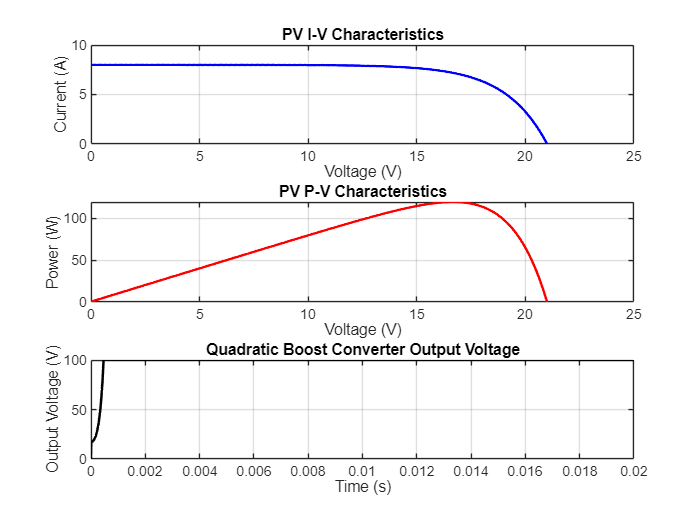


% Test the RBF Network
predicted_duty_cycle = sim(net, [V_pv; I_pv]);

%% Plot Results
figure;
subplot(3, 1, 1);
plot(V_pv, I_pv, 'b', 'LineWidth', 1.5);
xlabel('Voltage (V)');
ylabel('Current (A)');
title('PV I-V Characteristics');
grid on;

subplot(3, 1, 2);
plot(V_pv, P_pv, 'r', 'LineWidth', 1.5);
xlabel('Voltage (V)');
ylabel('Power (W)');
title('PV P-V Characteristics');
grid on;

subplot(3, 1, 3);
plot(time, vout, 'k', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Output Voltage (V)');
title('Quadratic Boost Converter Output Voltage');
grid on;


fprintf('Combined simulation completed successfully.\n');

Combined simulation completed successfully.
